# Identification

### System Definition

clc 
clear all
close all 
DuCy=20; 
I_Lo=5; V_Co=5;
Vg=24; Vd=0;

Vs=[Vg Vd];
X=[I_Lo V_Co];

### Integer order

[A,B,C,D,G_int] =flyback_ss(Vs,X,DuCy)

A = 	1.0e+07 *

   -0.0400   -7.6000
    0.0380   -0.0000


B =     40000000    76000000
           0           0


C =      0     1


D =      0     0


G_int =
 
                                            
  1e05 s^3 + 1.068e13 s^2 + 7.145e18 s      
                                            
                                  + 3.073e26
                                            
  ------------------------------------------
                                            
  s^4 + 8e05 s^3 + 5.792e13 s^2 + 2.31e19 s 
                                            
                                  + 8.341e26
                                            
 
Continuous-time transfer function.



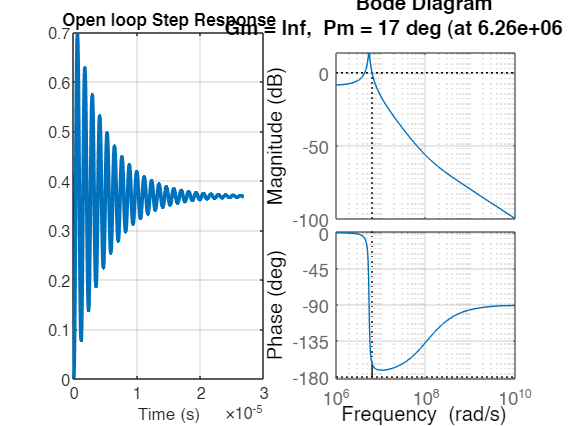

figure
subplot(1,2,1)
[y,t]=step(G_int); plot(t,y,'LineWidth',2)
grid on
title('Open loop Step Response')
xlabel('Time (s)')

subplot(1,2,2)
margin(G_int)
grid on

### Fractional order

% Vg=20;
% Vd=0;
% DuCy=0.5;
% 
% Im=0.5;
% Vc=7;
% 
% Vs=[Vg Vd];
% X=[Im Vc];
[G_fo] = flyback_fract(Vs,X,DuCy/100)

Fractional-order transfer function:
      -5e-06s^{0.95}+54.4
-------------------------------
5e-11s^{1.9}+5e-06s^{0.95}+2.56


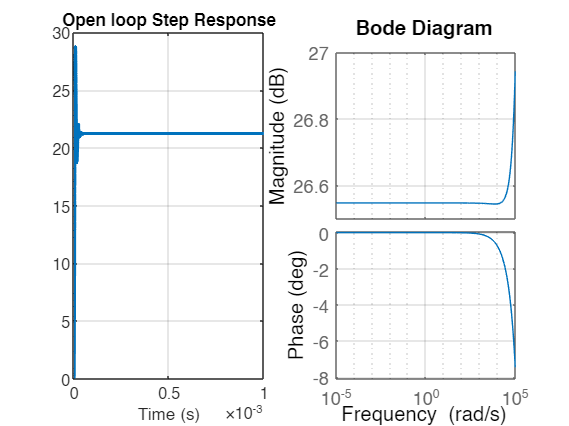


figure
subplot(1,2,1)
[y,t]=step(G_fo); plot(t,y,'LineWidth',2)
grid on
title('Open loop Step Response')
xlabel('Time (s)')

subplot(1,2,2)
bode(G_fo)
grid on

### Discretization for DT

Ts = 0.0001;
G_int_d = c2d(G_int,Ts,'tustin')

G_int_d =
 
                                            
  0.3685 z^4 + 1.473 z^3 + 2.21 z^2         
                                            
                          + 1.473 z + 0.3681
                                            
  ------------------------------------------
                                            
  z^4 + 3.999 z^3 + 5.996 z^2 + 3.997 z     
                                            
                                    + 0.9989
                                            
 
Sample time: 0.0001 seconds
Discrete-time transfer function.




G_int_d.Numerator

ans = 1×1 cell array
    {[0.3685 1.4734 2.2096 1.4728 0.3681]}


G_int_d.Denominator

ans = 1×1 cell array
    {[1 3.9988 5.9965 3.9966 0.9989]}



Kp = 0.000271;
Ti = 4.69e-10;
s=tf('s');
C = Kp*(1+1/(s*Ti))

C =
 
  1.271e-13 s + 0.000271
  ----------------------
        4.69e-10 s
 
Continuous-time transfer function.




F = feedback(C*G_int,1)

F =
 
                                             
   1.271e-08 s^4 + 28.46 s^3 + 2.896e09 s^2  
                                             
                      + 1.975e15 s + 8.329e22
                                             
  --------------------------------------------
                                              
  4.69e-10 s^5 + 0.0003752 s^4 + 2.719e04 s^3 
                                              
          + 1.373e10 s^2 + 3.931e17 s         
                                              
                                  + 8.329e22  
                                              
 
Continuous-time transfer function.



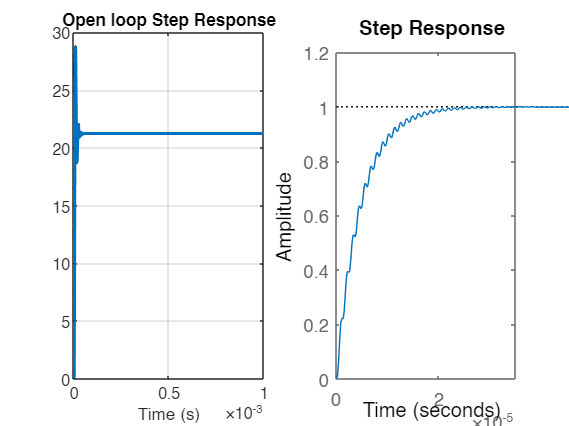

step(F)